# Threshold VAR



clear
clear classes

close all
rehash path

addpath ../sandbox
addpath ../bear


## Convenience functions

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];

defaultColors = get(0, "defaultAxesColorOrder");


## Prepare data and a reduced-form model

inputTbx = tablex.fromCsv("threshold_data.csv");

estimStart = datex.q(1948,2);
estimEnd = datex.q(2016,4);
estimSpan = datex.span(estimStart, estimEnd);

meta = threshold.Meta( ...
    endogenous=["dl_y",	"dl_cpi", "ir_tb", "stock_index"], ...
    thresholdVarName="stock_index", ...
    units="", ...
    exogenous=[], ...
    order=4, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    ...
    identificationHorizon=20, ...
    shockConcepts=[] ...
);

dataH = threshold.DataHolder(meta, inputTbx);


## Minnesota dummies


minnesotaD = dummies.Minnesota();
minnesotaD

minnesotaD =   Minnesota with properties:

             Lambda: 0.1000
           LagDecay: 1
    ExogenousLambda: 100
     Autoregression: 0.8000
          Exogenous: 0



estimatorR = estimator.Threshold(meta);

modelR = threshold.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR ...
    , dummies={minnesotaD} ...
    , stabilityThreshold=Inf ...
);

modelR.Estimator.Settings

ans =   Threshold with properties:

              VarThreshold: 10
                  MaxDelay: 4
          ThresholdPropStd: 0.0316
                    Burnin: 0
                 Exogenous: [4×1 logical]
            BlockExogenous: 0
            Autoregression: [4×1 double]
                   Lambda1: 0.1000
                   Lambda2: 0.5000
                   Lambda3: 1
                   Lambda4: [4×1 double]
                   Lambda5: 1.0000e-03
        StabilityThreshold: Inf
    MaxNumUnstableAttempts: 1000


rng(0)
modelR.initialize();
info5 = modelR.presample(10000);


 Presampling threshold.ReducedForm (Threshold) [10000]
 ―――――――――――――――――――――――――――――――――――――――――――――――――◼  100% 





thresholds = zeros(1, 10000);
for ii = 1:10000
    thresholds(ii) = modelR.Presampled{ii}.threshold;
end

mean(thresholds)

ans = 0.9306

### Start forecast

setting up the sample

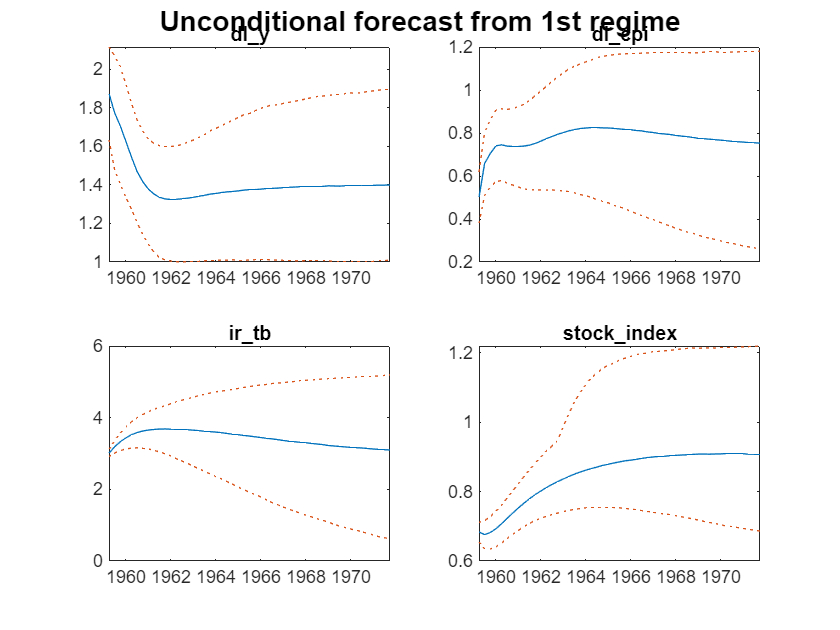


fcastStart1 = datex.shift(modelR.Meta.EstimationEnd, -230);
fcastEnd1 = datex.shift(modelR.Meta.EstimationEnd, -180);
fcastSpan1 = datex.span(fcastStart1, fcastEnd1);

fcastTbx1 = modelR.forecast(fcastSpan1, IncludeInitial=true);
fcastTbx1 = tablex.apply(fcastTbx1, prctileFunc); 
fcastPrctileTbx1 = tablex.flatten(fcastTbx1);

fcastStart2 = datex.shift(modelR.Meta.EstimationEnd, -105);
fcastEnd2 = datex.shift(modelR.Meta.EstimationEnd, -55);
fcastSpan2 = datex.span(fcastStart2, fcastEnd2);

fcastTbx2 = modelR.forecast(fcastSpan2, IncludeInitial=true);
fcastTbx2 = tablex.apply(fcastTbx2, prctileFunc); 
fcastPrctileTbx2 = tablex.flatten(fcastTbx2);


plotSettings = { ...
   {"color"}, {defaultColors(2,:); defaultColors(1,:); defaultColors(2,:)},  ...
   {"lineStyle"}, {":";"-";":"}, ...
};
% 
ch = visual.Chartpack( ...
      span=datex.span(fcastStart1, fcastEnd1), ...
      namesToPlot=[modelR.Meta.EndogenousNames], ...
     plotSettings=plotSettings ...
);

 ch.Captions = "Unconditional forecast from 1st regime";
 ch.plot(fcastPrctileTbx1);

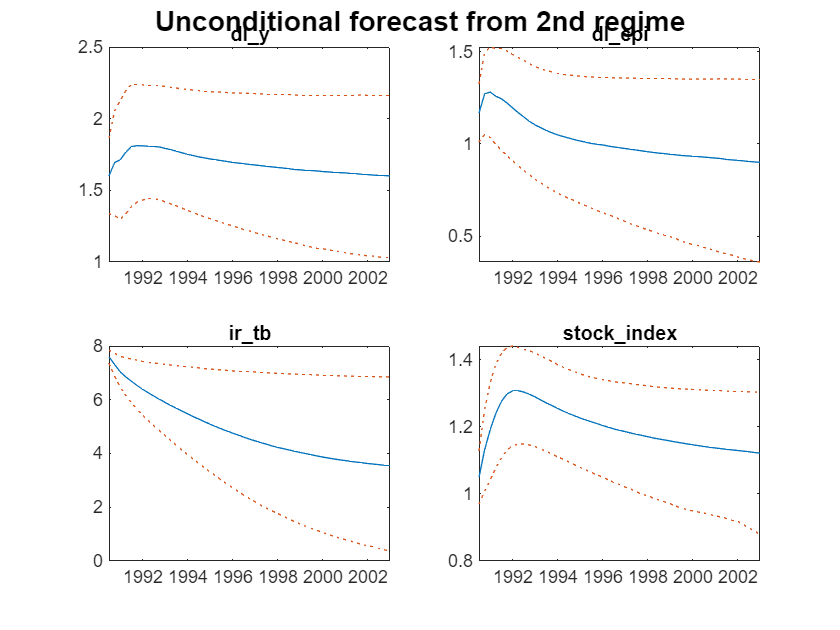


 ch = visual.Chartpack( ...
      span=datex.span(fcastStart2, fcastEnd2), ...
      namesToPlot=[modelR.Meta.EndogenousNames], ...
     plotSettings=plotSettings ...
);

 ch.Captions = "Unconditional forecast from 2nd regime";
 ch.plot(fcastPrctileTbx2);